P19    研究函数变化趋势

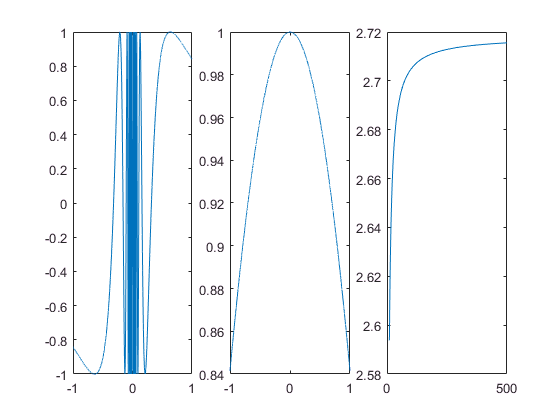

x = [-1 : .0001 : -.01 , .01 : .0001 : 1 ] ;
x3 = 10 : 500 ;
y1 = sin(1./x) ;
y2 = sin(x) ./ x ;
y3 = (1 + 1 ./ x3) .^ x3;
y4 = 2.71828 ;
subplot( 1 , 3 , 1) ,plot( x , y1 ) ,
subplot( 1 , 3 , 2) ,plot( x , y2 ) ,
subplot( 1 , 3 , 3) ,plot( x3 , y3 , x3 , y4 ) 


clear; syms x;
limit(sin(1/x) , x , 0 ),

$$ans = \mathrm{NaN}$$

limit(sin(x)/x , x , 0 ),

$$ans = 1$$

limit((1 + 1/x)^x , x ,inf ) ,

$$ans = \mathrm{e}$$

P20 复利问题

%m = input('m = ');
%c = (1 + .1/m) ^ (10 * m) 

P21 2.2.3

clear
syms x
limit(((1 + x ) ^ (1 / x) - exp( 1 ) ) / x , x , 0 )

$$ans = \mathrm{NaN}$$

P21    导数

syms x y 
y = x^2 * exp(2*x);
yx = diff(y ,x);
yxxxxx = diff( y , x , 5);
%y1 = simple( yx );
%y5 = simple( yxxxxx );
yx,yxxxxx;

$$yx = 2\,x\,{\mathrm{e}}^{2\,x}+2\,x^{2}\,{\mathrm{e}}^{2\,x}$$

x = 1 ; eval (yx) ,eval(yxxxxx)

ans = 29.5562

ans = 2.6009e+03

P22 将结果变成差分

x = [1 5 2 7 9 9];
diff(x)

ans =      4    -3     5     2     0


P22 极值和最值

figure
fplot('x*sin(x^2 - x - 1)',[-2 0]);

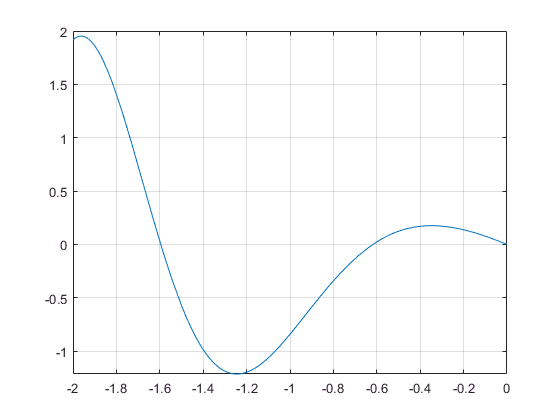

grid on


[x,f] = fminbnd('x*sin(x^2 - x - 1)',-2,0)

x = -1.2455

f = -1.2138


f = inline('x*sin(x^2 - x - 1)','x');
[x,f] = fminsearch(f,-1.2)

x = -1.2455

f = -1.2138


ff = inline('-x*sin(x^2 - x - 1)','x');
[x,f] = fminbnd(ff,-2,-1)

x = -1.9628

f = -1.9524


ff = inline('-x*sin(x^2 - x - 1)','x');
[x,f] = fminbnd(ff,-1,0)

x = -0.3473

f = -0.1762


ff = inline('-x*sin(x^2 - x - 1)','x');
[x,f] = fminsearch(ff,-2)

x = -1.9628

f = -1.9524


x = -2 : .01 : 0 ;
y = x .*sin(x.^2 - x - 1) ;
[m,k] = min(y)

m = -1.2137

k = 76


x(k)

ans = -1.2500